% Create path
clear all; close all; clc
addpath(genpath(cd)); % add all subfolders of cd to path

### Step 0: Aponeurosis depth range selection

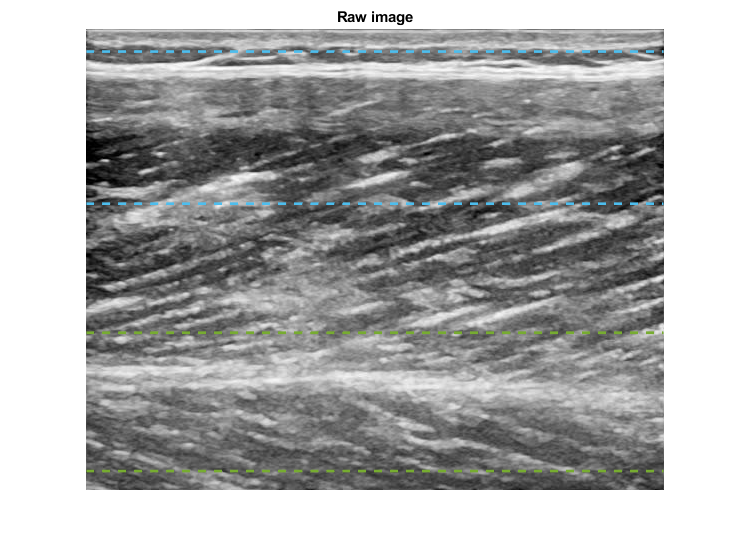

load('parms.mat'); % start with default parameters
imagename = 'example_ultrasound_image.mat';
load(['Example images\raw\single_images\', imagename])
[n,m] = size(data); % data needs to be a n-by-m numeric array

parms.apo.super.cut(1) = 0.05; parms.apo.super.cut(2) = 0.38; 
parms.apo.deep.cut(1) = 0.66; parms.apo.deep.cut(2) = 0.96; 

figure(1); imshow(data); title('Raw image'); color = get(gca,'colororder'); 
for i = 1:2
    line('xdata', [1 m] , 'ydata', n.*[parms.apo.super.cut(i) parms.apo.super.cut(i)],...
    'linewidth',2, 'linestyle', '--', 'color', color(6,:))
    
    line('xdata', [1 m] , 'ydata', n.*[parms.apo.deep.cut(i) parms.apo.deep.cut(i)],...
    'linewidth',2, 'linestyle', '--', 'color', color(5,:))
end

### Step 1: Filtering

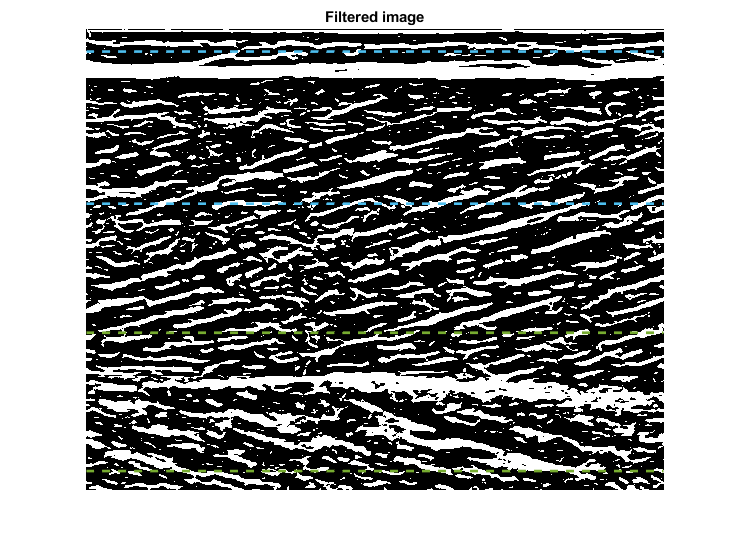

parms.apo.method = "Hough";
parms.apo.frangi.FrangiScaleRange(1) = 18; parms.apo.frangi.FrangiScaleRange(2) = 20;
parms.fas.frangi.FrangiScaleRange(1) = 1; parms.fas.frangi.FrangiScaleRange(2) = 2;
parms.apo.th = 0.5; parms.apo.sigma = 10;
parms.fas.th =0.2; 
parms.apo.show = true;

parms.apo.apox = round(linspace(parms.apo.apomargin, m-parms.apo.apomargin, parms.apo.napo));

figure(2)
[fas_thres, super_apo, deep_apo] = filter_usimage(data,parms);

### Step 2 & 3: Select aponeurosis objects and do Hough transform

% Define the horizontal aponeurosis spacing
apomargin = 100; apospacing = 10;
parms.apo.super.apox = apomargin:apospacing:(m-apomargin);
parms.apo.deep.apox = apomargin:apospacing:(m-apomargin);
parms.apo.deep.order = 1;
parms.extrapolation = true;
parms.show = true;

% Hough parameters parameters
parms.fas.range(1) = 10; parms.fas.range(2) = 80; 
parms.fas.npeaks = 5;

figure(3)
auto_ultrasound(data,parms);

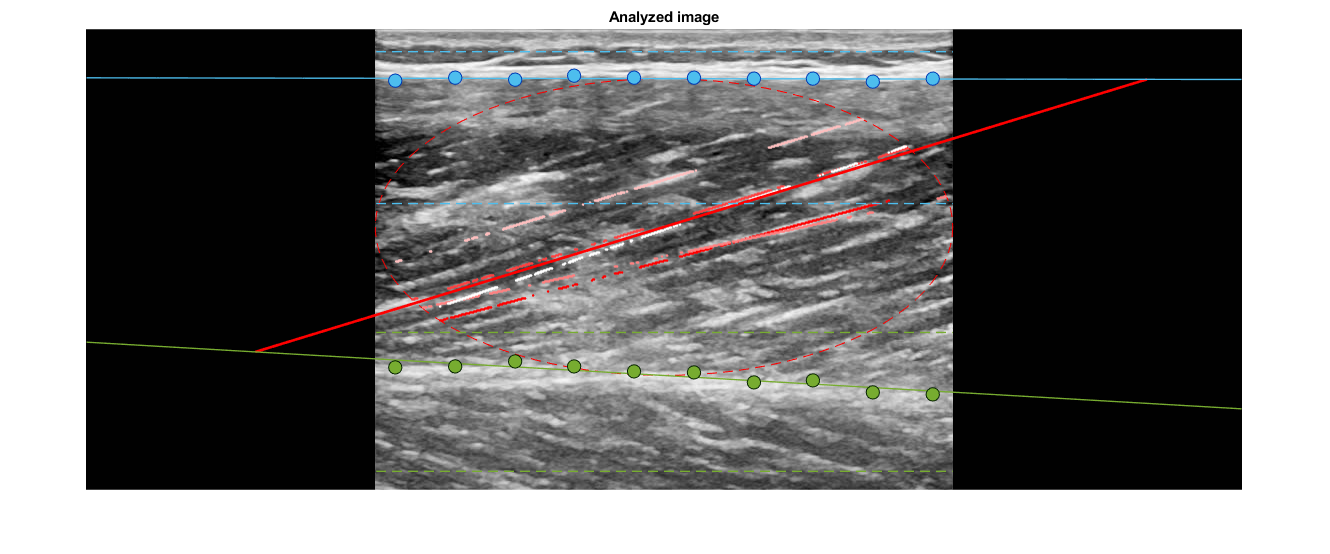

title('Analyzed image')

## Save parameters

whichparms = which('parms.mat');
parfolder = whichparms(1:end-length('parms.mat'));
cd(parfolder)

save(['parms_for_',imagename],'parms')